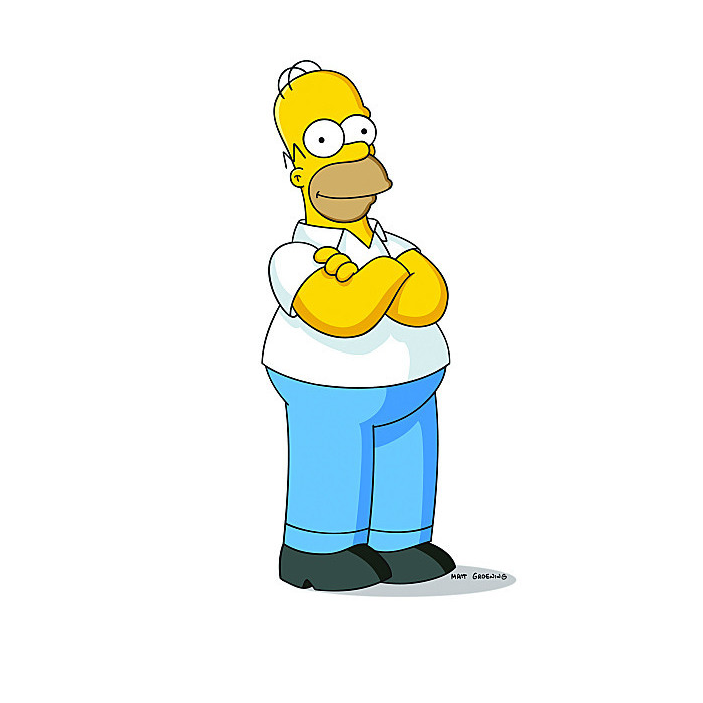

clear all;
bild = imread("bild2.jpg");
imshow(bild);

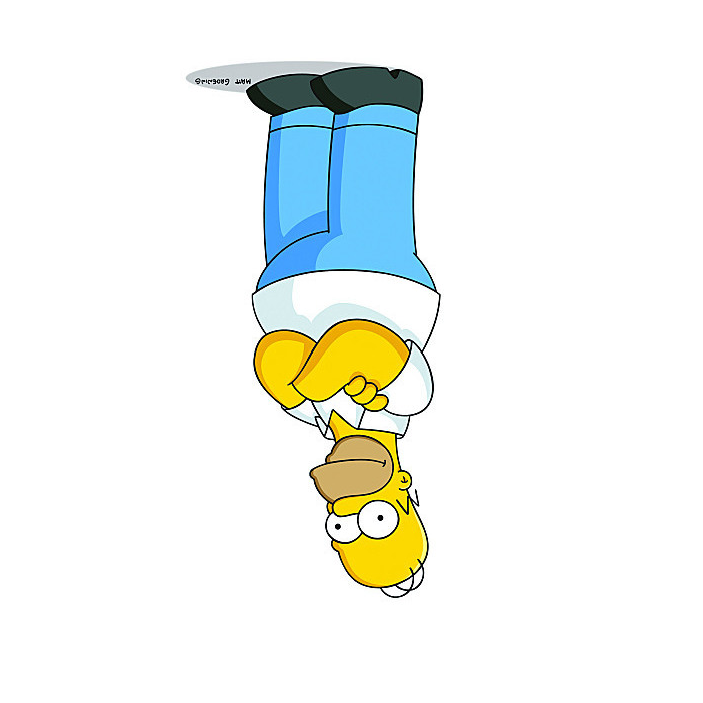

figure;
b = rotateLR(bild,180);
imshow(b);

function rotated_image = rotateLR(image_matrix, angle)
    % Validating input angle
    valid_angles = [0, 90, 180, 270, 360];
    if ~ismember(angle, valid_angles)
        error('Invalid rotation angle. Must be one of 0, 90, 180, 270, or 360 degrees.');
    end

    % Get the dimensions of the input image
    [rows, cols, channels] = size(image_matrix);

    % Initialize the rotated_image variable based on the rotation angle
    switch angle
        case 0
            rotated_image = image_matrix;
        case 90
            rotated_image = zeros(cols, rows, channels);
            for c = 1:channels
                for i = 1:rows
                    for j = 1:cols
                        rotated_image(j, rows - i + 1, c) = image_matrix(i, j, c);
                    end
                end
            end
            rotated_image = uint8(rotated_image);
        case 180
            rotated_image = zeros(rows, cols, channels);
            for c = 1:channels
                for i = 1:rows
                    for j = 1:cols
                        rotated_image(rows - i + 1, cols - j + 1, c) = image_matrix(i, j, c);
                    end
                end
            end
            rotated_image = uint8(rotated_image);
        case 270
            rotated_image = zeros(cols, rows, channels);
            for c = 1:channels
                for i = 1:rows
                    for j = 1:cols
                        rotated_image(cols - j + 1, i, c) = image_matrix(i, j, c);
                    end
                end
            end
            rotated_image = uint8(rotated_image);
        case 360
            rotated_image = image_matrix;  % Same as original image
    end
end
